# Peak Analysis

This example shows how to perform basic peak analysis. It will help you answer questions such as: How do I find peaks in my signal? How do I measure distance between peaks? How do I measure the amplitude of peaks of a signal which is affected by a trend? How do I find peaks in a noisy signal? How do I find local minima?

## 1- Load sample ECG data

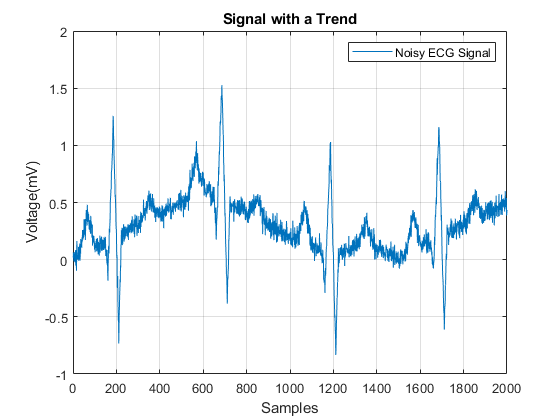

load noisyecg.mat

t = 1:length(noisyECG_withTrend);
figure
plot(t,noisyECG_withTrend)
title('Signal with a Trend')
xlabel('Samples');
ylabel('Voltage(mV)')
legend('Noisy ECG Signal')
grid on

## **2- Detrending Data**

The above signal shows a baseline shift and therefore does not represent the true amplitude. In order to remove the trend, fit a low order polynomial to the signal and use the polynomial to detrend it.

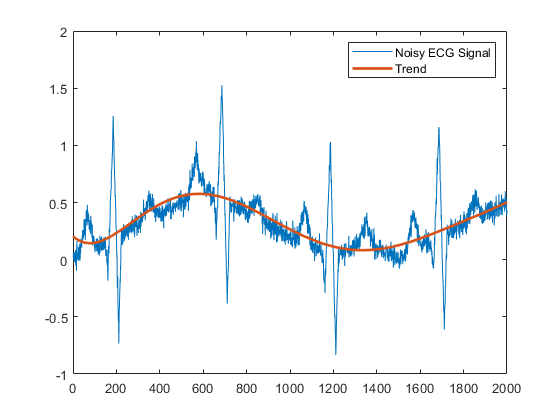

[p,s,mu] = polyfit((1:numel(noisyECG_withTrend))',noisyECG_withTrend,6);
f_y = polyval(p,(1:numel(noisyECG_withTrend))',[],mu);

plot(t,noisyECG_withTrend)
hold on
plot(t,f_y,'LineWidth',2)
legend('Noisy ECG Signal', 'Trend')

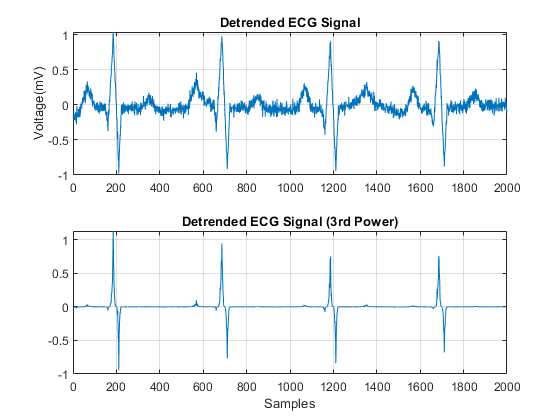


ECG_data = noisyECG_withTrend - f_y;        % Detrend data

ECG_data_p3 = ECG_data.^3;

figure
subplot(211)
plot(t,ECG_data)
grid on
title('Detrended ECG Signal')
ylabel('Voltage(mV)')

subplot(212)
plot(t,ECG_data_p3)
grid on
title('Detrended ECG Signal (3rd Power)')
xlabel('Samples')

After detrending, find the QRS-complex which is the most prominent repeating peak in the ECG signal. The QRS-complex corresponds to the depolarization of the right and left ventricles of the human heart. It can be used to determine a patient's cardiac rate or predict abnormalities in heart function. The following figure shows the shape of the QRS-complex in an ECG signal.

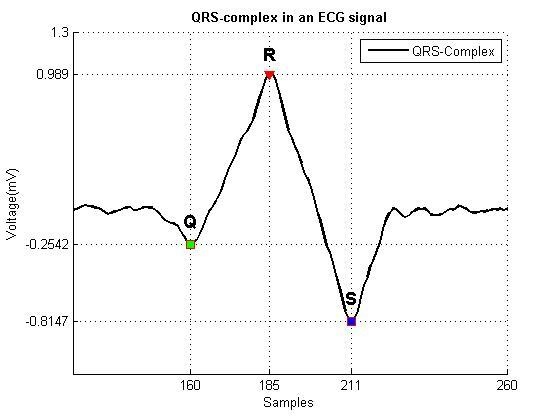

## 3- Finding R peaks

The R-peaks can be detected by thresholding peaks above 0.5mV. Notice that the R-peaks are separated by more than 200 samples. Use this information to remove unwanted peaks by specifying a 'MinPeakDistance'.

[~,locs_Rwave] = findpeaks(ECG_data_p3,'MinPeakHeight',0.5,...
                                    'MinPeakDistance',200);

## **4- Finding S-peaks**

For detection of the S-waves, find the local minima in the signal and apply thresholds appropriately. Local minima can be detected by finding peaks on an **inverted** version of the original signal.

ECG_inverted = -ECG_data_p3;
[~,locs_Swave] = findpeaks(ECG_inverted,'MinPeakHeight',0.5,...
                                        'MinPeakDistance',200);

The following plot shows the R-waves and S-waves detected in the signal.

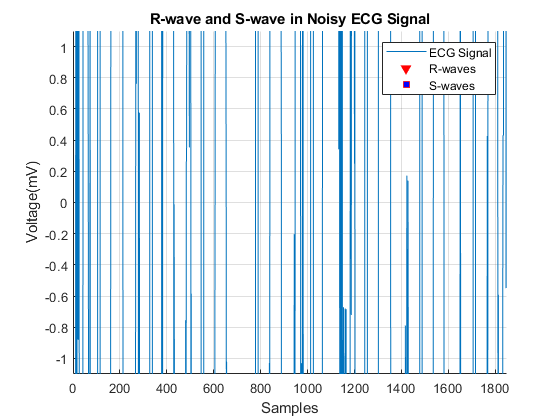

figure
hold on 
plot(t,ECG_data)
plot(locs_Rwave,ECG_data(locs_Rwave),'rv','MarkerFaceColor','r')
plot(locs_Swave,ECG_data(locs_Swave),'rs','MarkerFaceColor','b')
axis([0 1850 -1.1 1.1])
grid on
legend('ECG Signal','R-waves','S-waves')
xlabel('Samples')
ylabel('Voltage(mV)')
title('R-wave and S-wave in Noisy ECG Signal')

## **4- Finding Q-peaks**

Next, we try and determine the locations of the Q-peaks. Thresholding the peaks to locate the Q-peaks results in detection of unwanted peaks as the Q-peaks are buried in noise. We filter the signal first and then find the peaks. Savitzky-Golay filtering is used to remove noise in the signal.

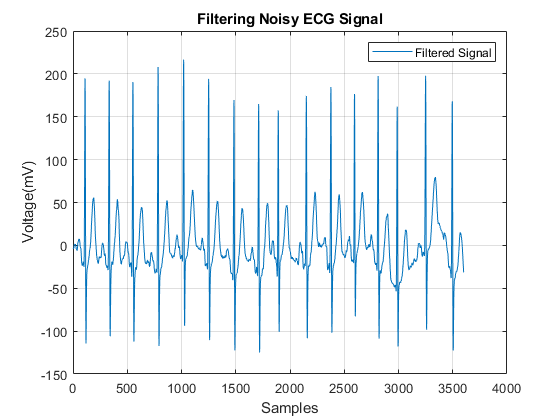

smoothECG = sgolayfilt(ECG_data,1,7);
% smoothECG = smooth(ECG_data,7,'sgolay',1);

figure
plot(t,smoothECG)
grid on
xlabel('Samples')
ylabel('Voltage(mV)')
legend('Filtered Signal')
title('Filtering Noisy ECG Signal')

We perform peak detection on the smooth signal and use logical indexing to find the locations of the Q-waves.

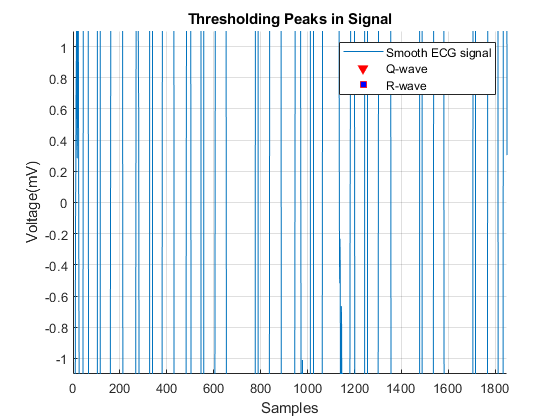

[~,min_locs] = findpeaks(-smoothECG,'MinPeakDistance',40);

% Peaks between -0.2mV and -0.5mV
locs_Qwave = min_locs(smoothECG(min_locs)>-0.5 & smoothECG(min_locs)<-0.2);

figure
hold on
plot(t,smoothECG); 
plot(locs_Qwave,smoothECG(locs_Qwave),'rs','MarkerFaceColor','g')
plot(locs_Rwave,smoothECG(locs_Rwave),'rv','MarkerFaceColor','r')
plot(locs_Swave,smoothECG(locs_Swave),'rs','MarkerFaceColor','b')
grid on
title('Thresholding Peaks in Signal')
xlabel('Samples')
ylabel('Voltage(mV)')
ax = axis;
axis([0 1850 -1.1 1.1])
legend('Smooth ECG signal','Q-wave','R-wave','S-wave')

The above figure shows that the QRS-complex successfully detected in the noisy ECG signal.

## **5- Error Between Noisy and Smooth Signal** 

Notice the average difference between the QRS-complex in the raw and the detrended filtered signal.

% Values of the Extrema
[val_Qwave, val_Rwave, val_Swave] = deal(smoothECG(locs_Qwave), smoothECG(locs_Rwave), smoothECG(locs_Swave));

meanError_Qwave = mean((noisyECG_withTrend(locs_Qwave) - val_Qwave))

meanError_Qwave = 0.2565

meanError_Rwave = mean((noisyECG_withTrend(locs_Rwave) - val_Rwave))

meanError_Rwave = 0.4068

meanError_Swave = mean((noisyECG_withTrend(locs_Swave) - val_Swave))

meanError_Swave = 0.1227

This demonstrates that it is essential to detrend a noisy signal for efficient peak analysis.

## **6- Peak Properties** 

Some important peak properties involve rise time, fall time, rise level, and fall level. These properties are computed for each of the QRS-complexes in the ECG signal. The average values for these properties are displayed on the figure below.

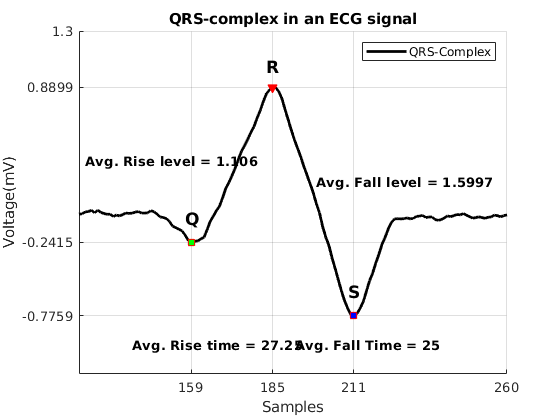

avg_riseTime = mean(locs_Rwave-locs_Qwave); % Average Rise time
avg_fallTime = mean(locs_Swave-locs_Rwave); % Average Fall time
avg_riseLevel = mean(val_Rwave-val_Qwave);  % Average Rise Level
avg_fallLevel = mean(val_Rwave-val_Swave);  % Average Fall Level

helperPeakAnalysisPlot(t,smoothECG,...
                    locs_Qwave,locs_Rwave,locs_Swave,...
                    val_Qwave,val_Rwave,val_Swave,...
                    avg_riseTime,avg_fallTime,...
                    avg_riseLevel,avg_fallLevel)